clear;

Aufgabe 5)

1.

t = 0:0.1:6*pi;

2.

y = exp(1i * t);

3.

realP = real(y);
imP = imag(y);

%realP = cos(t);
%imP = sin(t);

figure;
subplot(2,2,1);
plot(t, realP);
xlabel("time t");
ylabel("Re\{y\}");

subplot(2,2,2);
plot(t, imP);
xlabel("time t");
ylabel("Im\{y\}");


4. y = e^(t*i) = cos(t) * sin(t)

5.

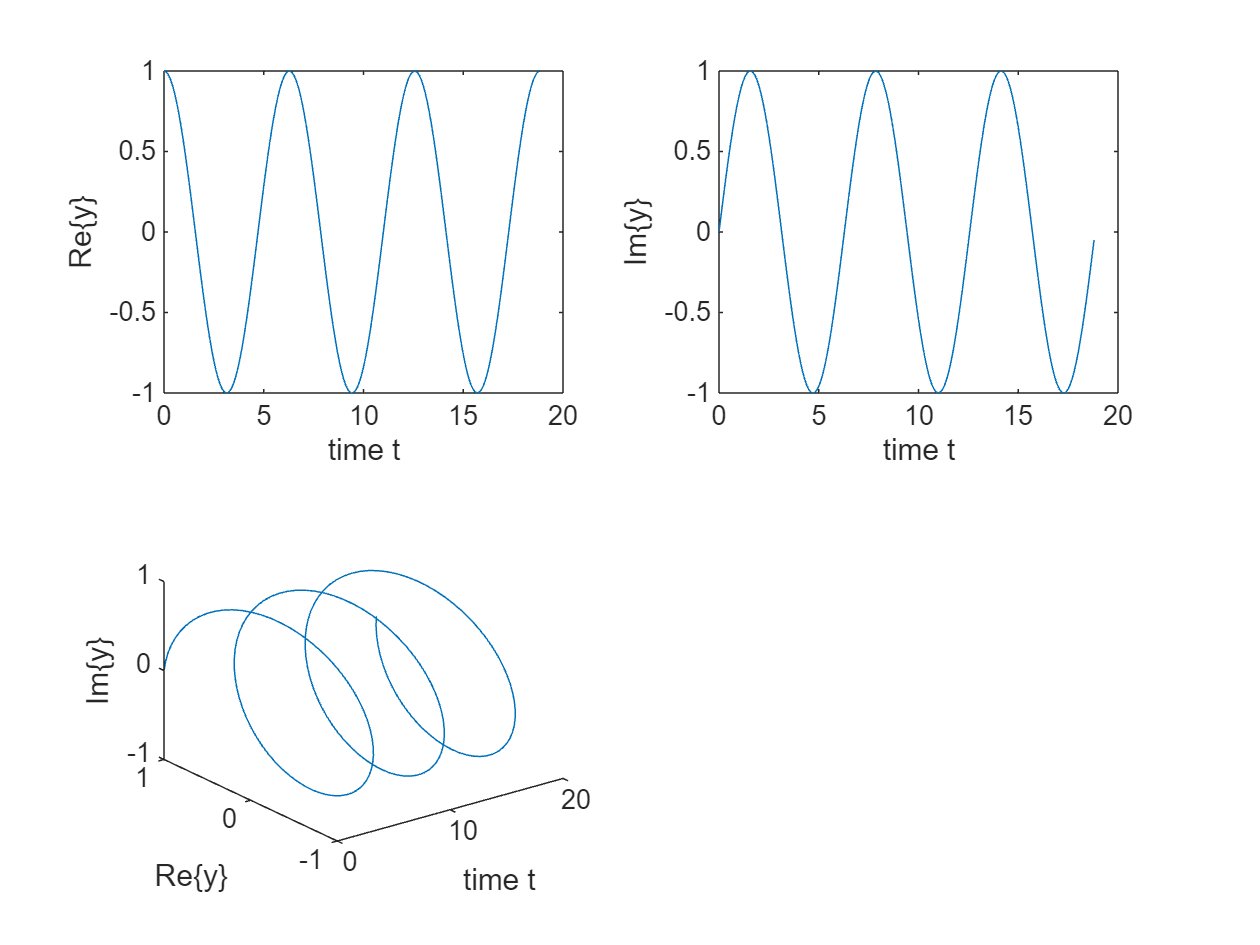

subplot(2,2,3);
plot3(t,realP,imP);
xlabel("time t");
ylabel("Re\{y\}");
zlabel("Im\{y\}");

Aufgabe 6)

x = pi/4 * [ones(1,256) 0 -1*ones(1,511) 0 ones(1,255)];

1.

Tp = 0.1;           % [s]
N = 1024;
t = 0: Tp / N :Tp;
Ts = Tp ./ N;       % [s]

2.

w0 = (2*pi) ./ Tp;  % [1/s]

3.

c0 = (1 ./ N) .* sum(x);
disp("c_0 = " + c0);

c_0 = 3.4694e-18


4.

n = 0 : 1 : N - 1;
e = exp(-1 .* 1i .* 2 .* pi .* ((1 .* n) ./ N));
c1 =  (1 / N) .* sum(x .* e);
disp("c_1 = " + c1);

c_1 = 0.5+5.6812e-17i


e = exp(-1 .* 1i .* 2 .* pi .* ((-1 .* n) ./ N));
cMinus1 =  (1 / N) .* sum(x .* e);
disp("c_-1 = " + cMinus1);

c_-1 = 0.5-5.6812e-17i


5.

konstCos = c1 + cMinus1;
konstSin = (c1 - cMinus1) * 1i;
disp("sin(w0t) * (" + konstSin + ") + cos(w0t) * (" + konstCos + ")");

sin(w0t) * (-1.1362e-16) + cos(w0t) * (1)


6.

n = 0 : 1 : N - 1;
m = -511:1:511;
cm = zeros(1, length(m));
for i = 1 : length(m)
    e = exp(-1 .* 1i .* 2 .* pi .* ((m(i) .* n) ./ N));
    cm(1, i) = sum(x .* e);
    disp("c_" + m(i) + " = " + cm(1, i));
end

c_-511 = -0.0048192-5.9343e-12i
c_-510 = 7.2486e-13-5.9295e-13i
c_-509 = 0.014458-3.4306e-14i
c_-508 = -3.0953e-13-1.2054e-12i
c_-507 = -0.024098-2.0617e-13i
c_-506 = -7.3719e-14+4.664e-13i
c_-505 = 0.033739-8.2712e-14i
c_-504 = -1.1035e-12-9.6273e-13i
c_-503 = -0.043383+8.36e-14i
c_-502 = -4.6751e-13-7.6676e-13i
c_-501 = 0.053031+1.0135e-12i
c_-500 = -1.0103e-14-2.4834e-14i
c_-499 = -0.062682+3.7841e-12i
c_-498 = 5.2625e-14+4.0593e-14i
c_-497 = 0.072338-1.5654e-13i
c_-496 = -4.4076e-14+1.0874e-12i
c_-495 = -0.082-5.1681e-13i
c_-494 = 2.8499e-13+6.0937e-14i
c_-493 = 0.091668-1.8985e-13i
c_-492 = -2.0095e-13-3.9775e-13i
c_-491 = -0.10134-9.4036e-14i
c_-490 = 5.6644e-13+6.1116e-13i
c_-489 = 0.11102+3.1697e-13i
c_-488 = 9.9976e-13-1.8472e-12i
c_-487 = -0.12072-5.8797e-13i
c_-486 = 8.9484e-14-1.8095e-13i
c_-485 = 0.13042-2.1005e-13i
c_-484 = 3.052e-13+3.407e-13i
c_-483 = -0.14013-1.3212e-13i
c_-482 = 7.494e-14-7.2017e-13i
c_-481 = 0.14985+2.2371e-13i
c_-480 = 3.8303e-14-1.4202e-12i
c_-479 

7.

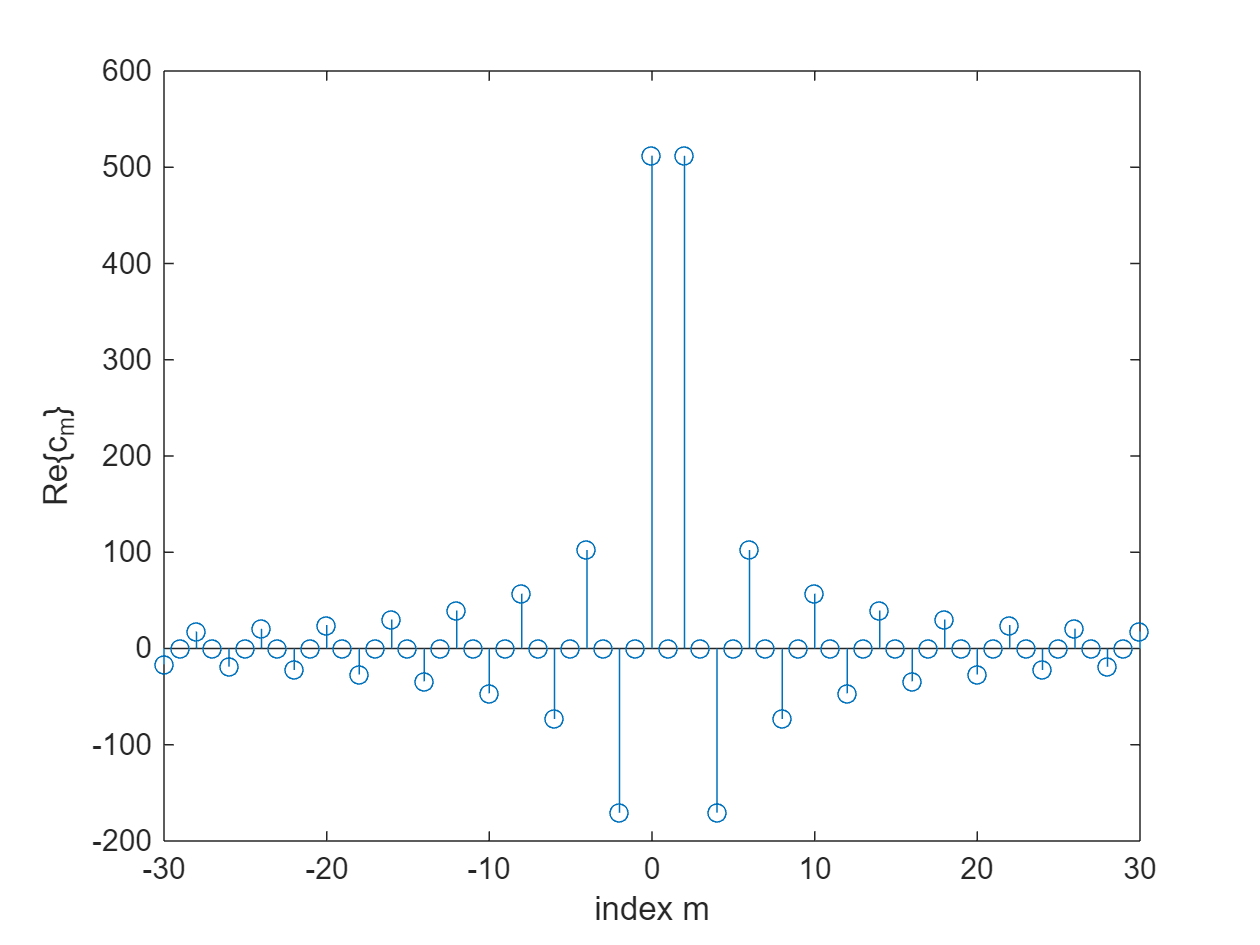

index = (511-30):1:(511+30);
xValues = -30:1:30;
cm3 = real(cm(index));

figure;
stem(xValues, cm3);
xlabel("index m");
ylabel("Re\{c_m\}");

8. Das Singnal hat für alle c_m = gerade keine Realteil.

9.

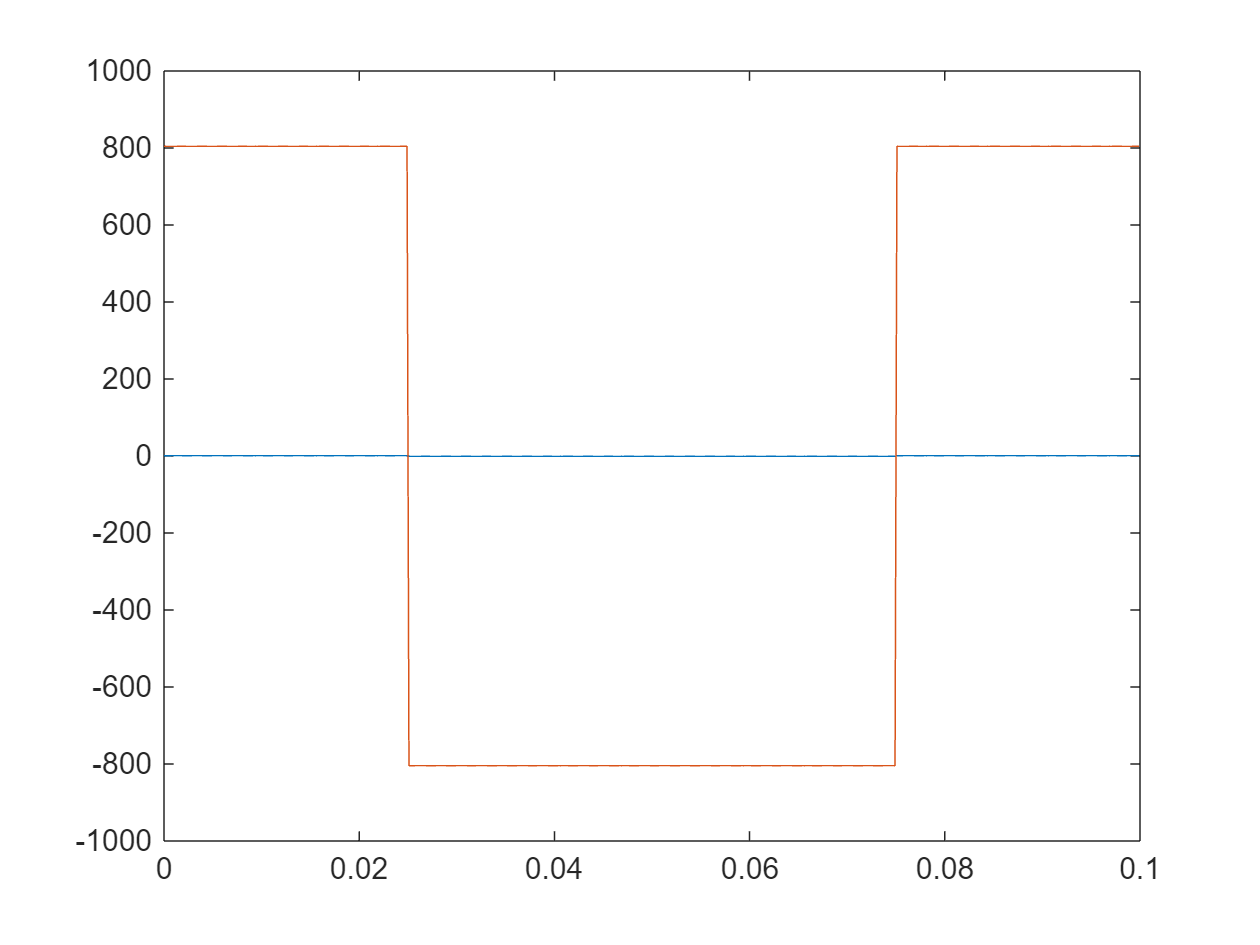

x2 = zeros(1, N);
for i = 1:N
    e = exp(1i .* m .* w0 .* t(i));
    x2(1, i) = sum(cm .* e);
end
figure;
plot(t(1:N), x, t(1:N), x2);